# Example 6.8 in book

Slicing strawberries edible part

## Reading img

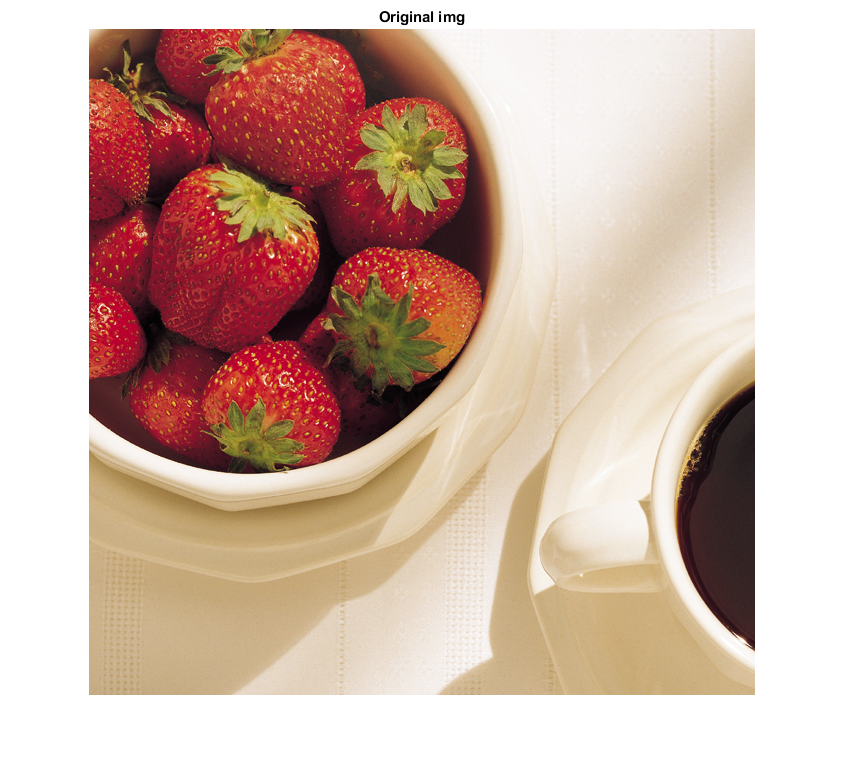

rgb_img = im2double(imread('strawberries_coffee.tif'));
img_size = size(rgb_img);
figure(1); imshow(rgb_img); title('Original img');

r =0.6863;
g =0.1608;
b =0.1922;

## Slicing with sphere formula

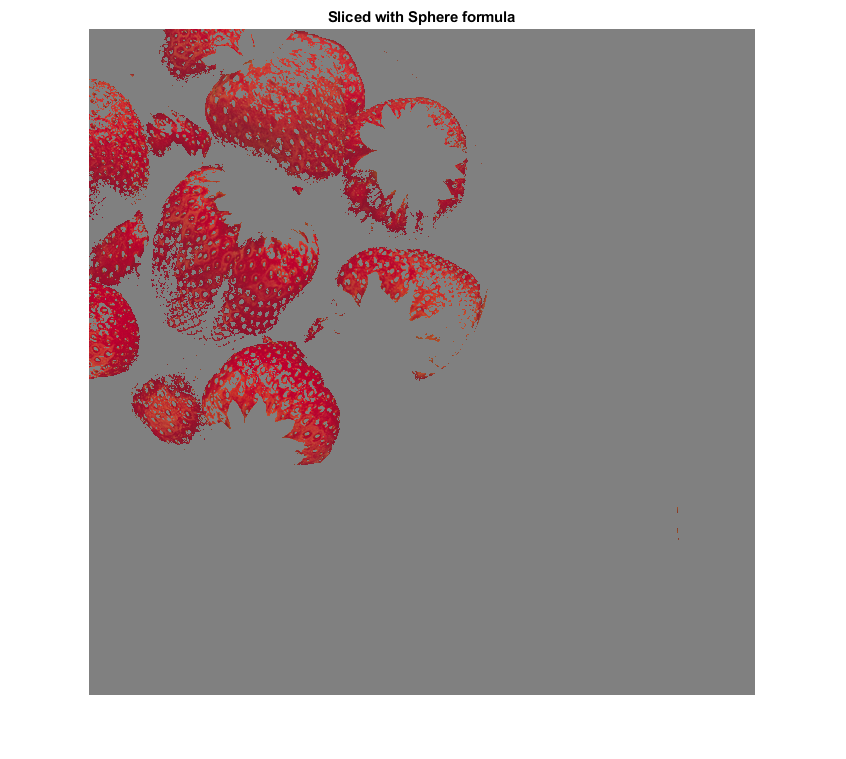

R =0.1765;
sliced_img = rgb_img;

for m=1:img_size(1)
    for n=1:img_size(2)
        if sumsqr(rgb_img(m,n,:) - reshape([r g b], 1, 1, 3)) > R^2
            sliced_img(m,n,:) = [0.5,0.5,0.5];
        end
    end
end
figure(2);
imshow(sliced_img); title('Sliced with Sphere formula');

## Slicing with box formula

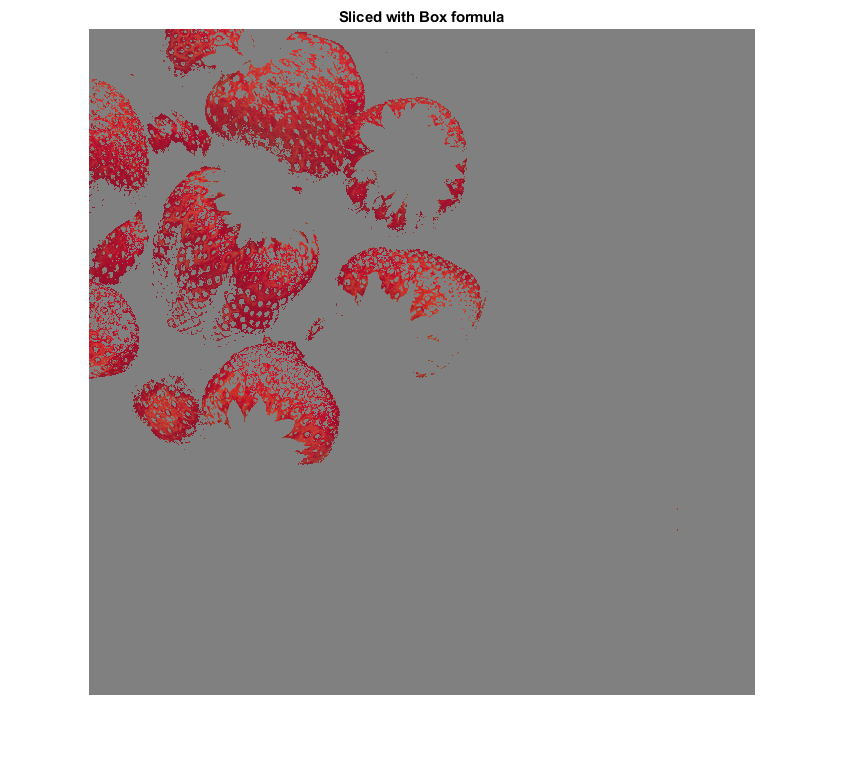

W =0.2549;
sliced_img = rgb_img;

for m=1:img_size(1)
    for n=1:img_size(2)
        if abs(rgb_img(m,n,1) - r) > W/2 ||...
           abs(rgb_img(m,n,2) - g) > W/2 || ...
           abs(rgb_img(m,n,3) - b) > W/2
            sliced_img(m,n,:) = [0.5,0.5,0.5];
        end
    end
end

figure(3);
imshow(sliced_img); title('Sliced with Box formula');